# Validation of Physics-Based Image Systems Simulation with 3D Scenes

## Figure 4

## 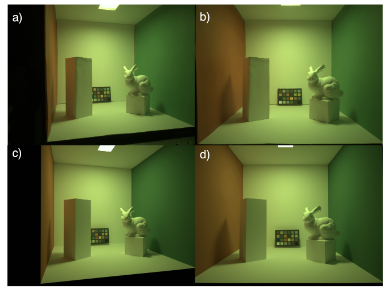

Fig. 4. Qualitative comparisons between the simulation and measurement from two camera positions. (a) and (b) are measurements; (c) and (d) are simulations.

%% Initialize ISET and Docker
ieInit;
if ~piDockerExists, piDockerConfig; end

% This is a low quality rendering for fast preview of the results. The
% configuration used in paper is commented next to each parameters
resolution = [252 189]; % [4032 3024]
nRaysPerPixel = 128; % 3072
nBounces = 6;

measPos1Path = fullfile(cboxRootPath, 'data', 'measurement', 'camerapos');

from = [-0.115 0.105 -0.405];
to = [0.135 0.115, 0.6];

measLeftImgPath = fullfile(measPos1Path, 'left', 'IMG_20210130_114111.dng');
label = 'Left';

oiLeft = cbOISim('from', from,...
                'to', to,...
                'resolution', resolution,...
                'n rays per pixel', nRaysPerPixel,... 
                'nbounces', nBounces,...
                'label', label,...
                'filmdistance', 0.49234);

Read 1 materials.
Read 1 textures.
***Scene parsed.

Scene materials: CornellBoxReference
-------------------------------
             name        type
         ____________    ____

    1    BackWall        uber
    2    BottomWall      uber
    3    CubeLarge       uber
    4    CubeSmall       uber
    5    LeftWall        uber
    6    RightWall       uber
    7    ShieldMat       uber
    8    TopWall         uber
    9    areaLightMat    uber

-------------------------------
Assigned reflectance to: ShieldMat
Assigned reflectance to: LeftWall
Assigned reflectance to: RightWall
Assigned reflectance to: BackWall
Assigned reflectance to: TopWall
Assigned reflectance to: BottomWall
Assigned reflectance to: CubeLarge
Assigned reflectance to: CubeSmall
Assigned reflect

camera = struct with fields:
            type: 'Camera'
         subtype: 'raytransfer'
    filmdistance: [1×1 struct]


Overwriting PBRT file /home/zhenglyu/git/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
Docker container vistalab/pbrt-v3-spectral:raytransfer-ellipse
Docker command
	docker run -ti --rm --workdir="/home/zhenglyu/git/iset3d/local/CornellBoxReference" --volume="/home/zhenglyu/git/iset3d/local/CornellBoxReference":"/home/zhenglyu/git/iset3d/local/CornellBoxReference" vistalab/pbrt-v3-spectral:raytransfer-ellipse pbrt --outfile /home/zhenglyu/git/iset3d/local/CornellBoxReference/renderings/CornellBoxReference.dat /home/zhenglyu/git/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
*** Rendering time for CornellBoxReference:  12.0 sec ***

  Reading image h=189 x w=252 x 31 spectral planes.


% oiWindow(oiLeft); oiSet(oiLeft, 'gamma', 0.5);

[prevImgSimLeft, prevImgMeasLeft, sensorSimLeft,...
    sensorMeasLeft, ~, ipSimLeft, ipMeasLeft] = cbSensorSim(oiLeft, 'meas img path', measLeftImgPath,...
                                                'illuscale', 0.8,...
                                                'noise flag', 2,...
                                                'vignetting', []);

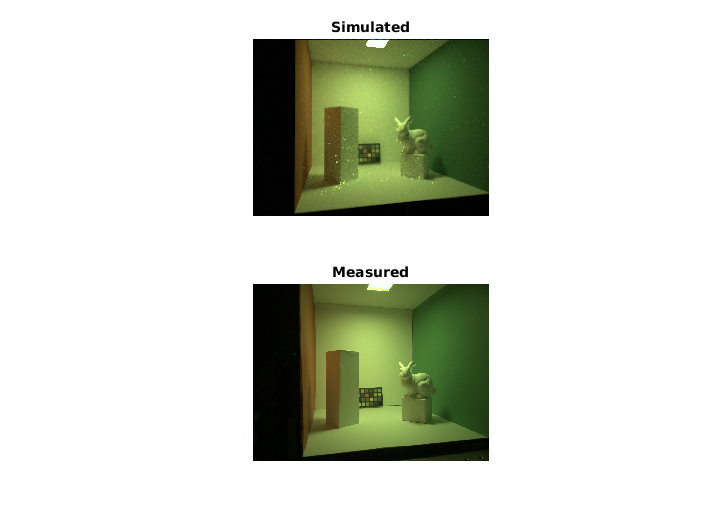

ieNewGraphWin; 
subplot(2, 1, 1); imshow(prevImgSimLeft); title('Simulated')
subplot(2, 1, 2); imshow(prevImgMeasLeft); title('Measured')

### Figure b and d


%% Center view
from = [0 0.10 -0.39];
to = [0 0.125, 0.6];
                                  
measCenerImgPath = fullfile(measPos1Path, 'center', 'IMG_20210130_111914.dng');
[sensor, info, ipMeasCenter] = cbDNGRead(measCenerImgPath, 'demosaic', true);
label = 'Center';

oiCtr = cbOISim('from', from,...
                'to', to,...
                'resolution', resolution,...
                'n rays per pixel', nRaysPerPixel,... 
                'nbounces', nBounces,...
                'label', label,...
                'filmdistance', 0.49234);

Read 1 materials.
Read 1 textures.
***Scene parsed.

Scene materials: CornellBoxReference
-------------------------------
             name        type
         ____________    ____

    1    BackWall        uber
    2    BottomWall      uber
    3    CubeLarge       uber
    4    CubeSmall       uber
    5    LeftWall        uber
    6    RightWall       uber
    7    ShieldMat       uber
    8    TopWall         uber
    9    areaLightMat    uber

-------------------------------
Assigned reflectance to: ShieldMat
Assigned reflectance to: LeftWall
Assigned reflectance to: RightWall
Assigned reflectance to: BackWall
Assigned reflectance to: TopWall
Assigned reflectance to: BottomWall
Assigned reflectance to: CubeLarge
Assigned reflectance to: CubeSmall
Assigned reflect

camera = struct with fields:
            type: 'Camera'
         subtype: 'raytransfer'
    filmdistance: [1×1 struct]


Overwriting PBRT file /home/zhenglyu/git/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
Docker container vistalab/pbrt-v3-spectral:raytransfer-ellipse
Docker command
	docker run -ti --rm --workdir="/home/zhenglyu/git/iset3d/local/CornellBoxReference" --volume="/home/zhenglyu/git/iset3d/local/CornellBoxReference":"/home/zhenglyu/git/iset3d/local/CornellBoxReference" vistalab/pbrt-v3-spectral:raytransfer-ellipse pbrt --outfile /home/zhenglyu/git/iset3d/local/CornellBoxReference/renderings/CornellBoxReference.dat /home/zhenglyu/git/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
*** Rendering time for CornellBoxReference:  12.6 sec ***

  Reading image h=189 x w=252 x 31 spectral planes.



[prevImgSimCtr, prevImgMeasCtr, sensorSimCtr,...
    sensorMeasCtr, ~, ipSimCtr, ipMeasCtr] = cbSensorSim(oiCtr, 'meas img path', measCenerImgPath,...
                                                'illuscale', 0.57,...
                                                'noise flag', 2,...
                                                'vignetting', []);                                         

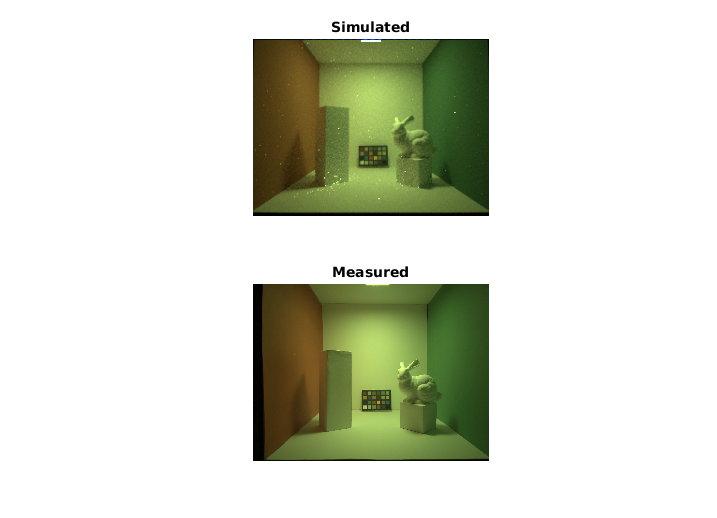

ieNewGraphWin; 
subplot(2, 1, 1); imshow(prevImgSimCtr); title('Simulated')
subplot(2, 1, 2); imshow(prevImgMeasCtr); title('Measured')